% ==========================
% NACA 4-Digit Airfoil Plot
% ==========================
% This script plots the upper/lower surfaces and camber lines for:
%   - NACA 2312
%   - NACA 2324
%   - NACA 4412
%   - NACA 4424
%
% where:
%   m = maximum camber (percentage of chord)
%   p = location of maximum camber (percentage of chord)
%   t = thickness (percentage of chord)
%
% Author: [Your Name]
% Date:   [Date]

clear; clc; close all;

## --- Main script portion: define airfoils and plot ---

(m, p, t) all in fraction-of-chord terms

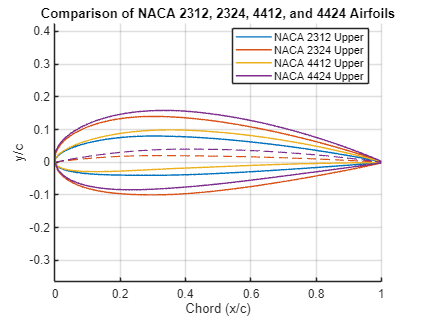

airfoilDefs = { ...
    'NACA 2312', NACA(0.02, 0.3, 0.12); ...
    'NACA 2324', NACA(0.02, 0.3, 0.24); ...
    'NACA 4412', NACA(0.04, 0.4, 0.12); ...
    'NACA 4424', NACA(0.04, 0.4, 0.24); ...
    };

figure('Name','NACA 4-Digit Airfoils','NumberTitle','off');
hold on; grid on;

colors = lines(size(airfoilDefs,1));  % Just to have distinct colors

for i = 1:size(airfoilDefs,1)
    name = airfoilDefs{i,1};

    [x, yc, xu, yu, xl, yl] = airfoilDefs{i,2}.naca_airfoil();

    % Plot upper surface
    plot(xu, yu, 'Color', colors(i,:), 'LineWidth', 1.2, ...
        'DisplayName',[name ' Upper']);
    % Plot lower surface
    plot(xl, yl, 'Color', colors(i,:), 'LineWidth', 1.2, ...
        'LineStyle','-', 'HandleVisibility','off');
    % Plot camber line (dashed)
    plot(x, yc, '--', 'Color', colors(i,:), ...
        'LineWidth', 1.0, 'HandleVisibility','off');
end

title('Comparison of NACA 2312, 2324, 4412, and 4424 Airfoils');
xlabel('Chord (x/c)');
ylabel('y/c');
axis equal;
legend('Location','best');
hold off;